# 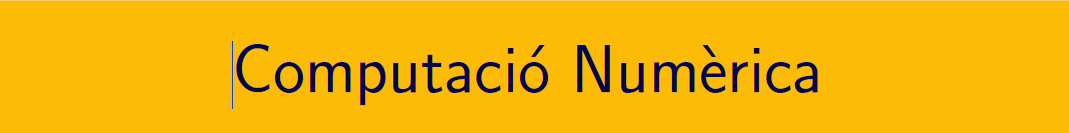

`===================================================================================`

# `Pràctica 13. Equacions diferencials ordinàries (III).`

`Document preparat per M. Àngela Grau Gotés - 25 de maig de 2023`

## `Mètodes multipas`

## `Exercici  `$y^{\prime}(t)=y(t)-t^2+1,,\quad y(0)=0.5,\quad 0\leq t\leq 2\,.$

`Solució analítica`

clearvars
syms y(t)
eqn = diff(y,t) == y-t^2+1;
cond = y(0) == 0.5;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 2\,t-\frac{{\mathrm{e}}^{t}}{2}+t^{2}+1$$

`La solució es pot respresentar a l'interval [0,1]`

## `Solucions aproximades numèricament O(h^4)`

- `Mètode RK4`

a = 0; alpha = 0.5;    % y(a) = alpha
b = 2;                 % y(b) = ...


- `Mètode `Adams-Basforth`-Moulton`

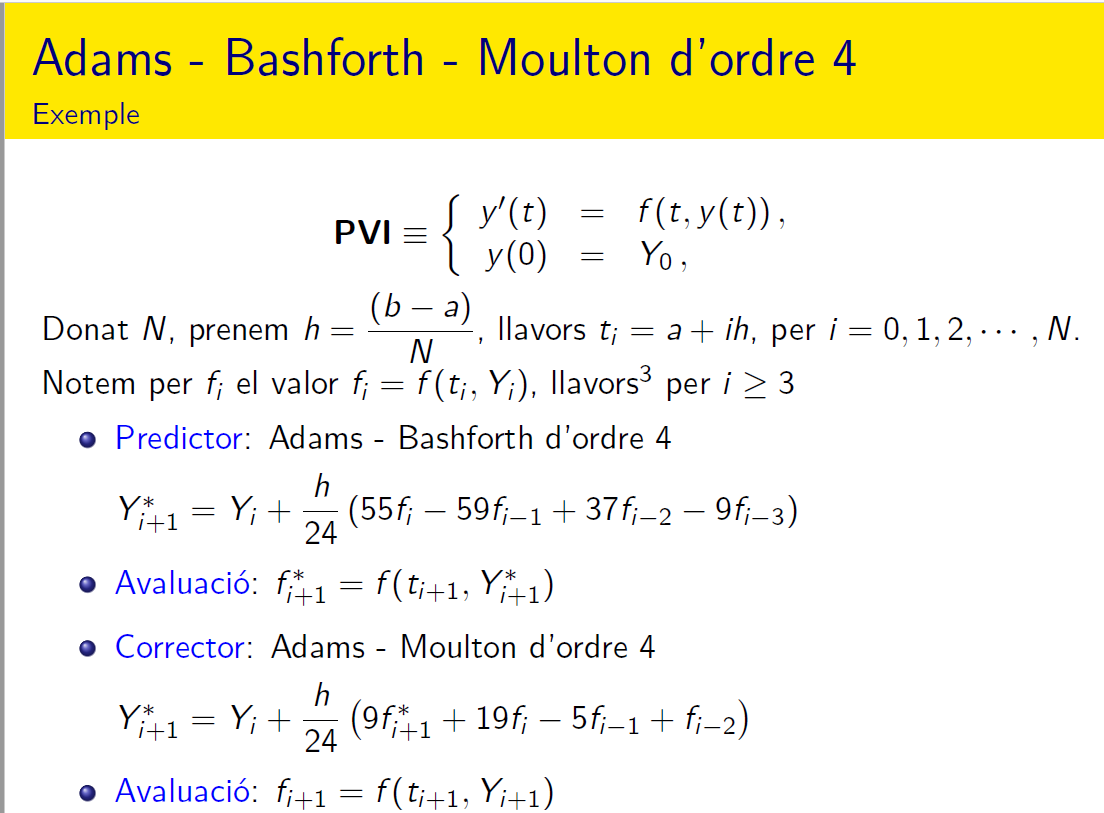

- `Mètode Adams-Moulton, els primers calculats per RK4`

% Mètode de  Adams-Basforth
a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(y-t.^2 + 1);
h = 0.1

h = 0.1000


% iniciem per RK4
wrk4  = RK4( f,a, a+3*h,h,alpha )

wrk4 =     1.0000    1.2100    1.4400    1.6900


w(1) = alpha;
w(2) = wrk4(2);
w(3) = wrk4(3);
w(4) = wrk4(4);
t = a:h:b;

N = length(t)

N = 11

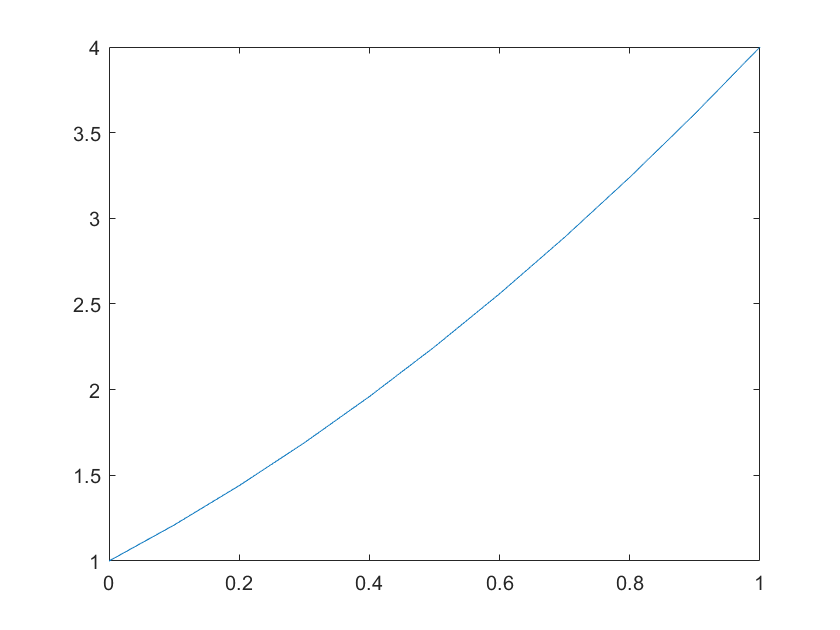


% Predictor Adams-Basforth
for i=4:N-1
    a1 = f(t(i),w(i));
    a2 = f(t(i-1),w(i-1));
    a3 = f(t(i-2),w(i-2));
    a4 = f(t(i-3),w(i-3));
    s = h*(55*a1-59*a2+37*a3-9*a4);
    Y(i+1)= w(i)+s/24;  %predictor adams-basforth
    
    a = f(t(i+1),Y(i+1));   %avaluacio 
    
    S = h*(9*a + 19*a1-5*a2 +a3) ;   % corrector adams-moulton
    w(i+1) = w(i) + S/24;
    %Z(i+1) = f(t(i+1),w(i+1));
    %tol = -19/270*(Y(i+1)- Z(i+1));
end


plot(t,w)

error_gl = double(abs(w(end)-ySol(b)))

error_gl = 1.3591

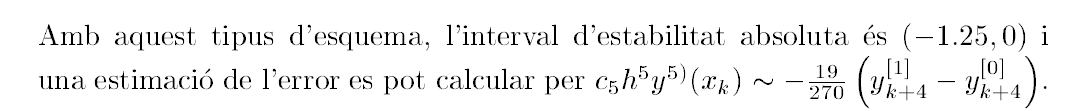

function  [w,t]  = RK4( f,a,b,h,alpha )
% Mètode RK4
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1 = h*f(t(i),w(i));
        k2 = h*f(t(i)+h/2,w(i) +k1/2);
        k3 = h*f(t(i)+h/2,w(i) +k2/2);
        k4 = h*f(t(i+1),w(i) +k3);
        w(i+1)=w(i)+(k1+2*k2+2*k3+k4)/6;
    end
end